# Sprawozdanie

# Sterowanie Adaptacyjne i Estymacja

## Modelowanie układu sterowania ze strukturą Model Following Control

#### Autorzy: Dawid Lisek, Paweł Mańka  

#### Nr indeksu: 402382, 402697 

#### Kierunek studiów: Automatyka i Robotyka

#### Specjalizacja: Komputerowe Systemy Sterowania

#### Grupa: wt 14:45 - 16:15 

## Inicjalizacja symulacji:

clear all

%inicjalizacja zmiennych symulacji

%inicjalizacja obiektów
k = 1; % wzmocnienie obiektu
G_num = k;
G_denum = [720 1764 1624 735 175 21 1];

G_m_num = [1];
G_m_denum = [5 5 4 2];
tau_m = 0.1;

%inicjalizacja regulatorów
Kp_r_m = 1;
Ki_r_m = 1;
Kd_r_m = 0;

Kp_r_k = 0.5;
Ki_r_k = 0.2;
Kd_r_k = 0.1;

% zakłócenie
z = 0.5;

%inicjalizacja symulacji
sample_time = 0.01;

%inicjalizacja switchy
ident_switch = 1; % 1 - skok jednostkowy; 2 - sygnał z regulatora R_m
correction_loop_switch = 2; % 1 - pętla korekcyjna włączona, 2 - pętla korekcyjna włączona
model_loop_switch = 2; % 1 - pętla z modelem włączona, 2 - pętla z modelem włączona
disturbance_switch = 2; % 1 - zakłócenie włączone, 2 - zakłócenie wyłączone

## Impulsowa i skokowa funkcja przejścia:

%ustawienie switchy na skok jednostkowy

ident_switch = 1 % 1 - skok jednostkowy; 2 - sygnał z regulatora R_m

ident_switch = 1

correction_loop_switch = 2 % 1 - pętla korekcyjna włączona, 2 - pętla korekcyjna włączona

correction_loop_switch = 2

model_loop_switch = 2 % 1 - pętla z modelem włączona, 2 - pętla z modelem włączona

model_loop_switch = 2

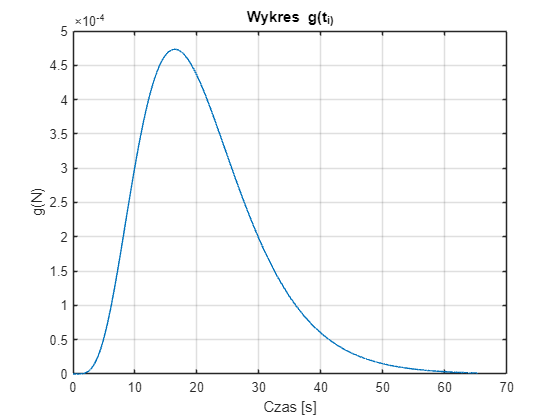

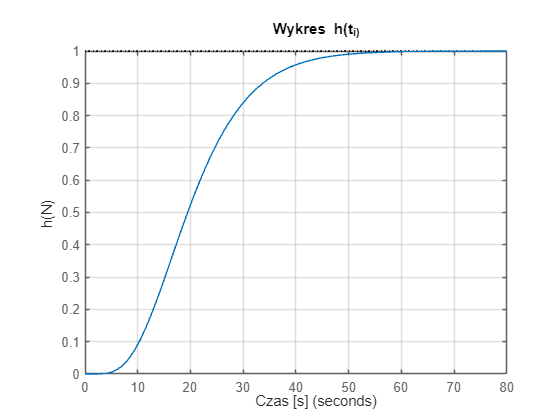


%ustawienie wstępnego czasu trwania symulacji
sys = tf(G_num, G_denum);
system_settling_time = stepinfo(sys).SettlingTime + 20;
stop_time = system_settling_time;

sim_out = sim("model_mfc.slx");
u = sim_out.u.Data;
y = sim_out.y.Data;
t = sim_out.tout;

[g, h] = impulse_step_transfer_function(u, y, t, sys);

## Identyfikacja modelem Strejca:

ans = "Znalezione opóźnienia obiektów"

tau_vec =     7.6909    4.8107    2.0920   -0.3973   -2.6750   -4.7738


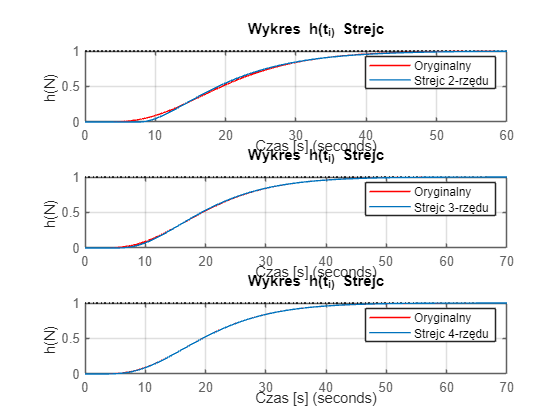

mean_squared_error =     1.4146    0.2592    0.0078


ans = "Znalezione najlepsze parametry obiektu"

n_m = 4

tau_m = 2.0920

T_m = 4.7327

[n_m, tau_m, T_m] = two_point_Strejc(t, h, stop_time);

## Aktualizacja modelu:

syms s
p = (T_m * s + 1)^(n_m);

G_m_num = k;
G_m_denum = sym2poly(p);
G_m = tf(G_m_num, G_m_denum, 'InputDelay',tau_m)

G_m =
 
                                       1
  exp(-2.09*s) * ---------------------------------------------
                 501.7 s^4 + 424 s^3 + 134.4 s^2 + 18.93 s + 1
 
Continuous-time transfer function.
Model Properties


## Strojenie regulatorów:

figure

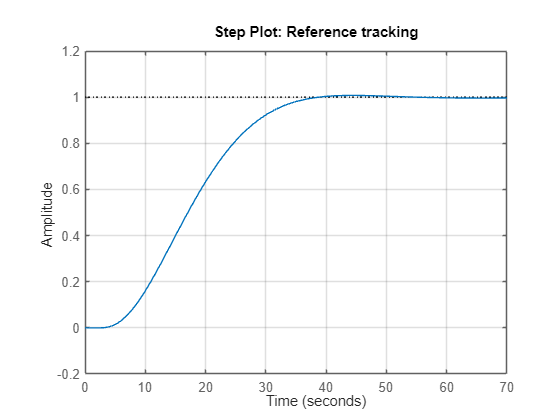

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/35.6579;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.662129;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[C,pidInfo] = pidtune(G_m,'PID',wc2,opts);

% Clear Temporary Variables
clear wc2 PM opts

% Get desired loop response
Response2 = getPIDLoopResponse(C,G_m,'closed-loop');

% Plot the result
stepplot(Response2)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response2

Kp_r_m = (1/(46 * k)) * ((7*n_m + 16)/(n_m - 2))

Kp_r_m = 0.4783

Ti_r_m = (T_m / 15)*(7*n_m + 16)

Ti_r_m = 13.8825

Ki_r_m = Kp_r_m / Ti_r_m

Ki_r_m = 0.0345

Td_r_m = T_m * ((n_m^2 + 4*n_m + 3)/(7*n_m + 16))

Td_r_m = 3.7646

Kd_r_m = Kp_r_m * Td_r_m

Kd_r_m = 1.8005

Kp_r_k = C.Kp

Kp_r_k = 0.7727

Ki_r_k = C.Ki

Ki_r_k = 0.0559

Kd_r_k = C.Kd

Kd_r_k = 2.6718

## Uruchomienie symulacji:

z = 0.5;
ident_switch = 2; % 1 - skok jednostkowy; 2 - sygnał z regulatora R_m
correction_loop_switch = 1; % 1 - pętla korekcyjna włączona, 2 - pętla korekcyjna wyłączona
model_loop_switch = 1; % 1 - pętla z modelem włączona, 2 - pętla z modelem wyłączona
disturbance_switch = 1; % 1 - zakłócenie włączone, 2 - zakłócenie wyłączone
stop_time = 500;
sim("model_mfc.slx")

ans =   Simulink.SimulationOutput:

                   tout: [50001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Nowy obiekt:

p = (s + 1)*(2*s + 1)*(3*s + 1)*(4*s + 1)*(7*s + 1)*(9*s + 1);

G_num = 1;
G_denum = sym2poly(p)

G_denum =         1512        3534        3029        1240         258          26           1


## Impulsowa i skokowa funkcja przejścia:

%ustawienie switchy na skok jednostkowy

ident_switch = 1 % 1 - skok jednostkowy; 2 - sygnał z regulatora R_m

ident_switch = 1

correction_loop_switch = 2 % 1 - pętla korekcyjna włączona, 2 - pętla korekcyjna włączona

correction_loop_switch = 2

model_loop_switch = 2 % 1 - pętla z modelem włączona, 2 - pętla z modelem włączona

model_loop_switch = 2

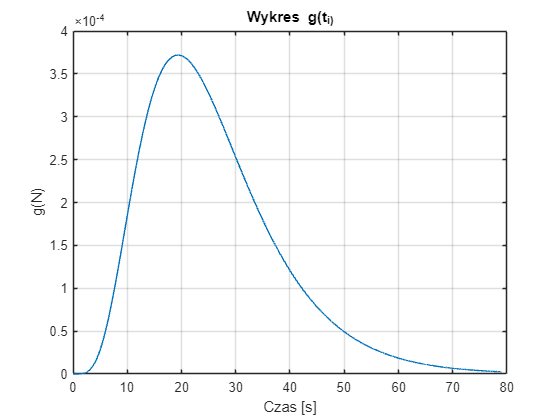

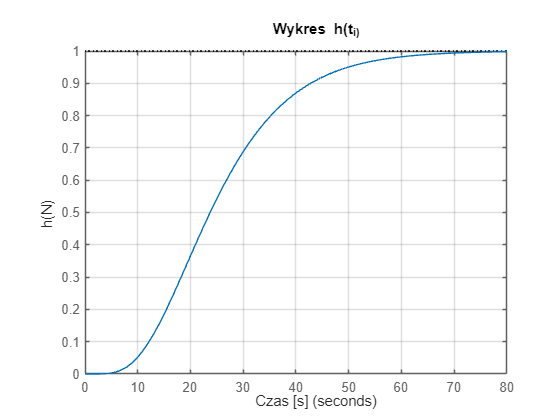


%ustawienie wstępnego czasu trwania symulacji
sys = tf(G_num, G_denum);
system_settling_time = stepinfo(sys).SettlingTime + 20;
stop_time = system_settling_time;

sim_out = sim("model_mfc.slx");
u = sim_out.u.Data;
y = sim_out.y.Data;
t = sim_out.tout;

[g, h] = impulse_step_transfer_function(u, y, t, sys);

## Identyfikacja modelem Strejca:

ans = "Znalezione opóźnienia obiektów"

tau_vec =     8.4019    4.4717    0.7981   -2.5362   -5.5815   -8.3923


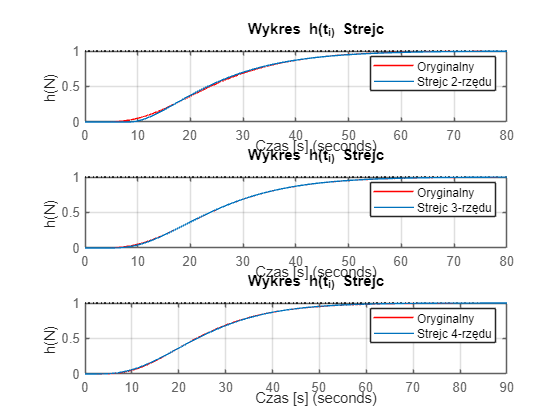

mean_squared_error =     1.0408    0.0600    0.1228


ans = "Znalezione najlepsze parametry obiektu"

n_m = 3

tau_m = 4.4717

T_m = 7.1842

[n_m, tau_m, T_m] = two_point_Strejc(t, h, stop_time);

## Aktualizacja modelu:

syms s
p = (T_m * s + 1)^(n_m);

G_m_num = k;
G_m_denum = sym2poly(p);
G_m = tf(G_m_num, G_m_denum, 'InputDelay',tau_m)

G_m =
 
                                  1
  exp(-4.47*s) * -----------------------------------
                 370.8 s^3 + 154.8 s^2 + 21.55 s + 1
 
Continuous-time transfer function.
Model Properties


## Strojenie regulatorów dla nowego obiektu:

figure

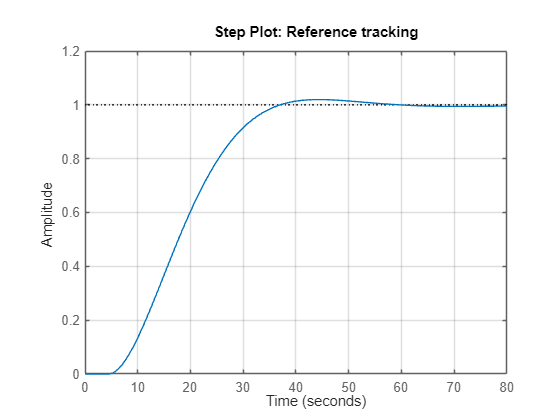

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/36.3547;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM2 = 100*0.648457;

% Define options for pidtune command
opts2 = pidtuneOptions('PhaseMargin',PM2);

% PID tuning algorithm for linear plant model
[C2,pidInfo2] = pidtune(G_m,'PID',wc,opts2);

% Clear Temporary Variables
clear wc PM2 opts2

% Get desired loop response
Response = getPIDLoopResponse(C2,G_m,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response


Kp_r_m = (1/(46 * k)) * ((7*n_m + 16)/(n_m - 2))

Kp_r_m = 0.8043

Ti_r_m = (T_m / 15)*(7*n_m + 16)

Ti_r_m = 17.7209

Ki_r_m = Kp_r_m / Ti_r_m

Ki_r_m = 0.0454

Td_r_m = T_m * ((n_m^2 + 4*n_m + 3)/(7*n_m + 16))

Td_r_m = 4.6600

Kd_r_m = Kp_r_m * Td_r_m

Kd_r_m = 3.7483

Kp_r_k = C2.Kp

Kp_r_k = 1.0011

Ki_r_k = C2.Ki

Ki_r_k = 0.0545

Kd_r_k = C2.Kd

Kd_r_k = 4.5998

## Uruchomienie symulacji z nowym obiektem:

z = 0.5;
ident_switch = 2; % 1 - skok jednostkowy; 2 - sygnał z regulatora R_m
correction_loop_switch = 1; % 1 - pętla korekcyjna włączona, 2 - pętla korekcyjna wyłączona
model_loop_switch = 1; % 1 - pętla z modelem włączona, 2 - pętla z modelem wyłączona
disturbance_switch = 1; % 1 - zakłócenie włączone, 2 - zakłócenie wyłączone
stop_time = 500;
sim("model_mfc.slx")

ans =   Simulink.SimulationOutput:

                   tout: [50001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
